# NeuralNetsPack quick start

Default fitting uses a learnable B-spline basis. Use it when the target is sharp or nonsmooth.

------------------------------------------------------
Optimization will terminate after 600 Iterations.
------------------------------------------------------
Iteration : 2 , Cost :       1.99099166 
Iteration : 4 , Cost :       1.97232030 
Iteration : 6 , Cost :       1.97227324 
Iteration : 8 , Cost :       1.96942109 
Iteration : 10 , Cost :       1.96524147 
Iteration : 12 , Cost :       1.95568545 
Iteration : 14 , Cost :       1.93110379 
Iteration : 16 , Cost :       1.87066310 
Iteration : 18 , Cost :       1.69471709 
Iteration : 20 , Cost :       1.29687708 
Iteration : 22 , Cost :       0.79730149 
Iteration : 24 , Cost :       0.49450016 
Iteration : 26 , Cost :       0.33855867 
Iteration : 28 , Cost :       0.26623274 
Iteration : 30 , Cost :       0.21527788 
Iteration : 32 , Cost :       0.18486914 
Iteration : 34 , Cost :       0.15605559 
Iteration : 36 , Cost :       0.13807104 
Iteration : 38 , Cost :       0.13660503 
Iteration : 40 , Cost :       0.12040043 
Iter

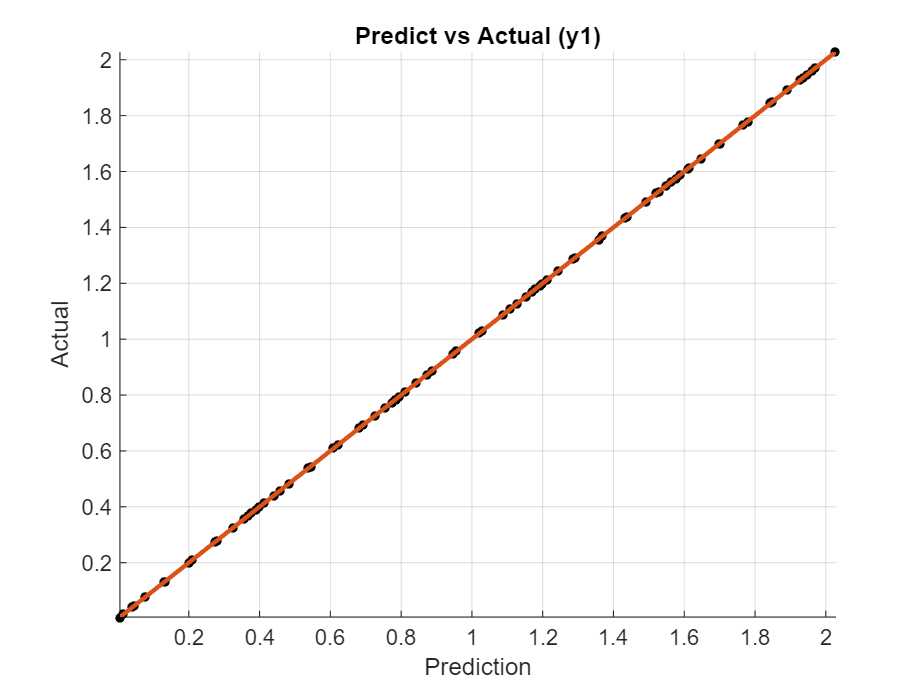

clear; clc; close all;
thisDir = fileparts(mfilename('fullpath'));
[~, thisFolder] = fileparts(thisDir);
if strcmp(thisFolder, 'source')
    packRoot = fileparts(fileparts(thisDir));
else
    packRoot = fileparts(thisDir);
end
addpath(packRoot);
setupNeuralNetPath(struct('savePath', false, 'verbose', false));

x = linspace(-2, 2, 80);
y = abs(x) + 0.1*sin(8*x);

model = NeuralFit(x, y, [1, 1]);

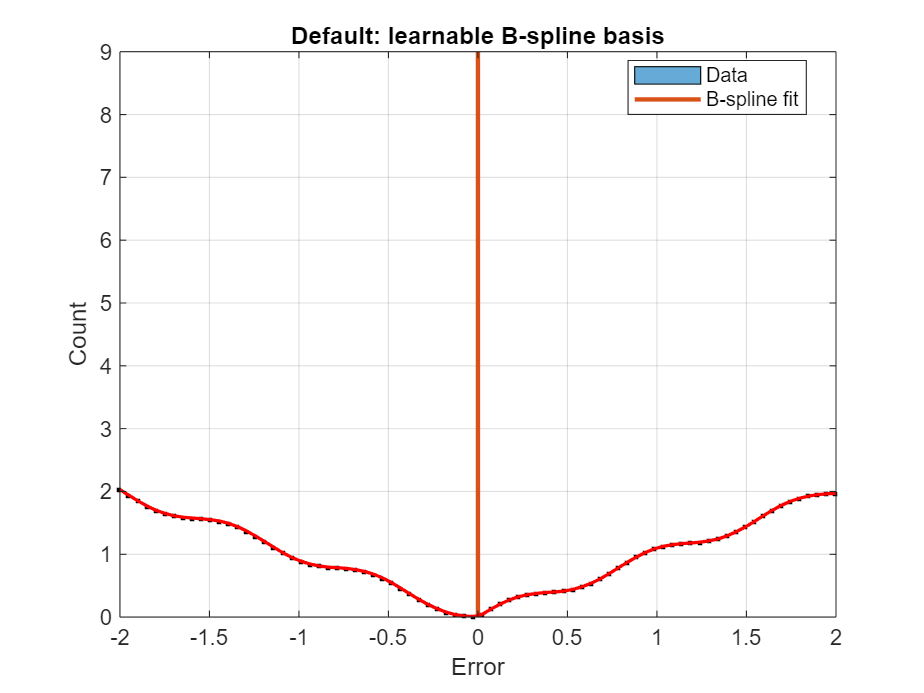

yHat = model.Evaluate(x);

plot(x, y, 'k.', x, yHat, 'r-', 'LineWidth', 1.5);
grid on;
legend('Data', 'B-spline fit', 'Location', 'best');
title('Default: learnable B-spline basis');

## Fixed basis for smooth data

Gaussian is the fixed-basis default alias.

------------------------------------------------------
Optimization will terminate after 100 Iterations.
------------------------------------------------------
Iteration : 1 , Cost :       1.98182231 
Iteration : 2 , Cost :       1.97015928 
Iteration : 3 , Cost :       1.96658411 
Iteration : 4 , Cost :       1.96205071 
Iteration : 5 , Cost :       1.95301205 
Iteration : 6 , Cost :       1.93288744 
Iteration : 7 , Cost :       1.90656152 
Iteration : 8 , Cost :       1.86761555 
Iteration : 9 , Cost :       1.81664838 
Iteration : 10 , Cost :       1.74387839 
Iteration : 11 , Cost :       1.66012310 
Iteration : 12 , Cost :       1.55098269 
Iteration : 13 , Cost :       1.42287949 
Iteration : 14 , Cost :       1.28276776 
Iteration : 15 , Cost :       1.12689942 
Iteration : 16 , Cost :       0.97592184 
Iteration : 17 , Cost :       0.83192524 
Iteration : 18 , Cost :       0.70739181 
Iteration : 19 , Cost :       0.60810994 
Iteration : 20 , Cost :       0.52814234 
---------

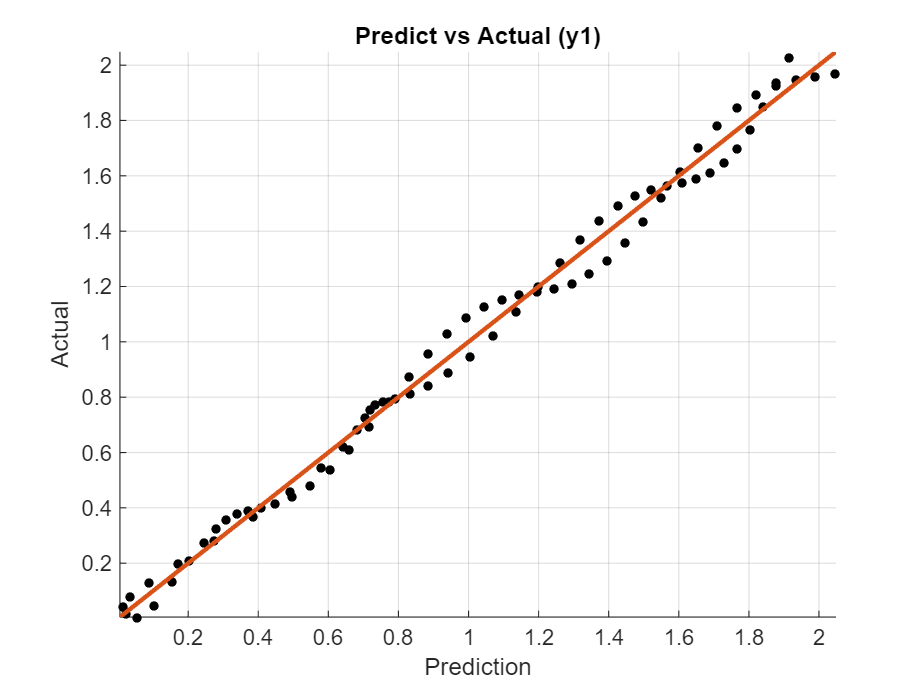

fixedModel = NeuralFit(x, y, [1, 1], 'basis', 'fixed', ...
    'stage1Iterations', 20, 'stage2Iterations', 80);

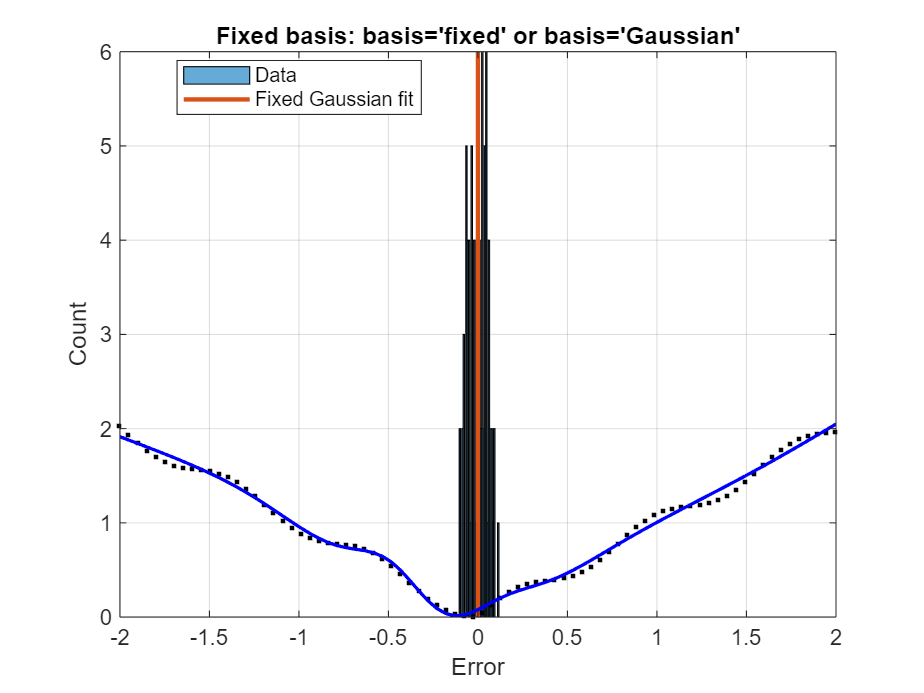

fixedHat = fixedModel.Evaluate(x);

plot(x, y, 'k.', x, fixedHat, 'b-', 'LineWidth', 1.5);
grid on;
legend('Data', 'Fixed Gaussian fit', 'Location', 'best');
title("Fixed basis: basis='fixed' or basis='Gaussian'");